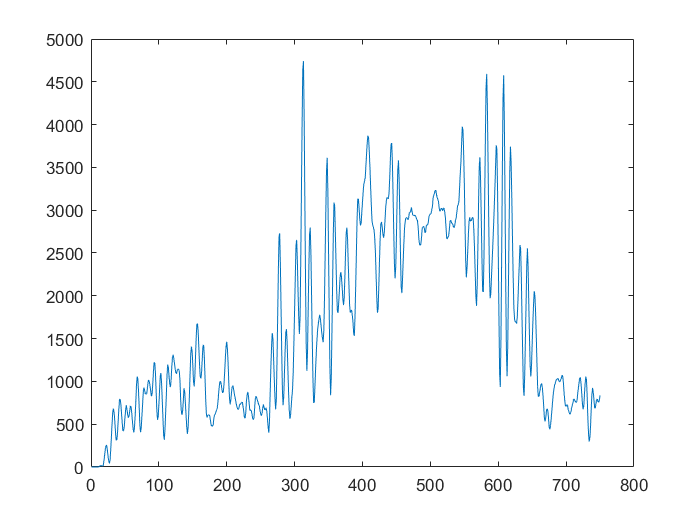

clear
load Apkirpta_ideali_preambule_d.mat %yy-ideali diferencijuota preambule
%Koreliacijos max priklausomybe nuo amplitudes

amplitude_duom = [];
preambules_max_duom = [];
rms_duom = [];
eng_duom = [];
preambules_max_duom2 = [];
preambules_max1_error_max = [];
preambules_max1_error_min = [];
preambules_max2_error_max = [];
preambules_max2_error_min = [];
temp_preambules_max1_error_max = [];
temp_preambules_max1_error_min = [];
temp_preambules_max2_error_max = [];
temp_preambules_max2_error_min = [];
neteisingi = [];

viso_max_duom = [];
viso_max_duom2 = [];
viso_langas = [];
viso_pastumimas = [];

viso_viso_rms = [];
viso_viso_eng = [];
viso_viso_langas = [];
viso_viso_pastumimas = [];
viso_neteisingi = [];

kiekvienas_max = [];
kiekvienas_eng = [];
kiekvienas_max2 = [];

pastumimasN = 2;
fdiskret = 10E6;
tdiskret = 1/fdiskret;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;

dataSend = "101101";
vienetu_generuoti = 100;

%Ref itampa 1.4V
langas_temp = [];
pastumimas_temp = [];
%for langas = 70:10:100
for pastumimasN = 2%1:1:10
    langas = 50;
    amplitude_duom = [];
    rms_duom = [];
    eng_duom = [];
    preambules_max_duom = [];
    preambules_max_duom2 = [];
    langas_temp = [];
    neteisingi = 0;
    pastumimas_temp = [];
    temp_preambules_max1_error_max = [];
    temp_preambules_max1_error_min = [];
    temp_preambules_max2_error_max = [];
    temp_preambules_max2_error_min = [];

    for generuojama_amplitude = 0.5:0.05:1.4
        vid_max_y = 0;
        vid_max_y2 = 0;
        vid_rms_y = 0;
        vid_eng_y = 0;
        vienetai = 0;
        
        nepataikyta = 0;
        
        sugeneruoti_max = zeros(1, vienetu_generuoti);
        sugeneruoti_max2 = zeros(1, vienetu_generuoti);
        kiekvienas_max_temp = zeros(1, vienetu_generuoti);
        kiekvienas_max2_temp = zeros(1, vienetu_generuoti);
        kiekvienas_eng_temp = zeros(1, vienetu_generuoti);
        
        for i = 1:vienetu_generuoti
            [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, generuojama_amplitude);
            
            ADCsignal2 = [ADCsignal];
            pastumtas = [zeros(1, pastumimasN), ADCsignal2(1:length(ADCsignal2)-pastumimasN)];
            diferencijuotasPilnas = ADCsignal2 - pastumtas;
            yy = GenerateConv(diferencijuotasPilnas, diferencijuotaPreambule); %diferencijuotas
            %y = GenerateConv(y, yy); %diferencijuotas DVIGUBAI
            y = GenerateConv(ADCsignal2, idealPreambule); %Nediferencijuoptas
            %[maksimumai, indeksai] = maxk(y(1:350),2);
            [maksimumai, indeksai] = maxk(y(1:330),2);
            max_y = maksimumai(1);
            max_y2 = maksimumai(2);
            index_y = indeksai(1);
            sugeneruoti_max(i) = max_y;
            sugeneruoti_max2(i) = max_y2;
            if index_y > 300 && index_y < 330
            %if index_y > 320 && index_y < 345
                vienetai = vienetai + 1;
                vid_max_y = vid_max_y + max_y;
                vid_rms_y = vid_rms_y + rms(ADCsignal2(index_y-langas:index_y));
                vid_eng_y = vid_eng_y + sum(abs(ADCsignal2(index_y-langas:index_y) .* ADCsignal2(index_y-langas:index_y)))/langas;
                vid_max_y2 = vid_max_y2 + max_y2;

                kiekvienas_max_temp(vienetai)= max_y;
                kiekvienas_eng_temp(vienetai) = sum(abs(ADCsignal2(index_y-langas:index_y)));
                kiekvienas_max2_temp(vienetai)= max_y2;
            else
                nepataikyta = nepataikyta + 1;
            end
            
        end

        kiekvienas_max = [kiekvienas_max; kiekvienas_max_temp];
        kiekvienas_max2 = [kiekvienas_max2; kiekvienas_max2_temp];
        kiekvienas_eng = [kiekvienas_eng; kiekvienas_eng_temp];
       
        %{
        [a, ~] = max(sugeneruoti_max);
        temp_preambules_max1_error_max = [temp_preambules_max1_error_max, a];
        [a, ~] = min(sugeneruoti_max);
        temp_preambules_max1_error_min = [temp_preambules_max1_error_min, a];
    
        [a, ~] = max(sugeneruoti_max2);
        temp_preambules_max2_error_max = [temp_preambules_max2_error_max, a];
        [a, ~] = min(sugeneruoti_max2);
        temp_preambules_max2_error_min = [temp_preambules_max2_error_min, a];
        %}
        %{
        a = rms(sugeneruoti_max);
        temp_preambules_max1_error_max = [temp_preambules_max1_error_max, a];
        temp_preambules_max1_error_min = [temp_preambules_max1_error_min, a];
        a = rms(sugeneruoti_max2);
        temp_preambules_max2_error_max = [temp_preambules_max2_error_max, a];
        temp_preambules_max2_error_min = [temp_preambules_max2_error_min, a];
        %}

        a = prctile(sugeneruoti_max,70);
        temp_preambules_max1_error_max = [temp_preambules_max1_error_max, a];
        temp_preambules_max1_error_min = [temp_preambules_max1_error_min, a];
        a = prctile(sugeneruoti_max2,70);
        temp_preambules_max2_error_max = [temp_preambules_max2_error_max, a];
        temp_preambules_max2_error_min = [temp_preambules_max2_error_min, a];
    
        vid_max_y = vid_max_y / vienetai; %Skaiciuojam vidurki
        vid_rms_y = vid_rms_y / vienetai;
        vid_eng_y = vid_eng_y / vienetai;
        vid_max_y2 = vid_max_y2 / vienetai; %Skaiciuojam vidurki
    
        amplitude_duom = [amplitude_duom, generuojama_amplitude];
        neteisingi = [neteisingi, nepataikyta];
        rms_duom = [rms_duom, vid_rms_y];
        eng_duom = [eng_duom, vid_eng_y];
        preambules_max_duom = [preambules_max_duom, vid_max_y];
        preambules_max_duom2 = [preambules_max_duom2, vid_max_y2];
        langas_temp = [langas_temp, langas];
        pastumimas_temp = [pastumimas_temp, pastumimasN];
    end
    preambules_max1_error_max = [preambules_max1_error_max; temp_preambules_max1_error_max];
    preambules_max1_error_min = [preambules_max1_error_min; temp_preambules_max1_error_min];
    preambules_max2_error_max = [preambules_max2_error_max; temp_preambules_max2_error_max];
    preambules_max2_error_min = [preambules_max2_error_min; temp_preambules_max2_error_min];
    
    viso_neteisingi = [viso_neteisingi; neteisingi];
    viso_viso_langas = [viso_viso_langas; langas_temp];
    viso_viso_pastumimas = [viso_viso_pastumimas; pastumimas_temp];
    viso_viso_rms = [viso_viso_rms; rms_duom];
    viso_viso_eng = [viso_viso_eng; eng_duom];
    viso_max_duom = [viso_max_duom; preambules_max_duom];
    viso_max_duom2 = [viso_max_duom2; preambules_max_duom2];
    viso_langas = [viso_langas, langas];
    viso_pastumimas = [viso_pastumimas, pastumimasN];
end

plot(y)

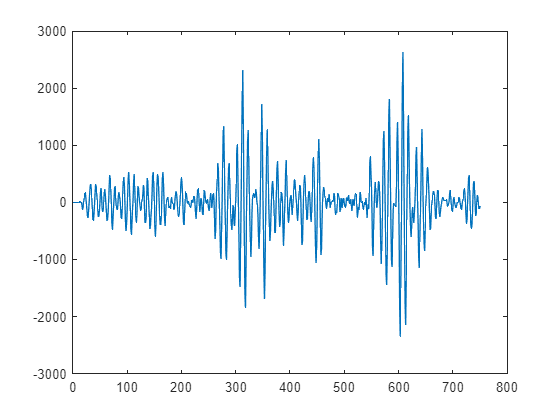

plot(yy)

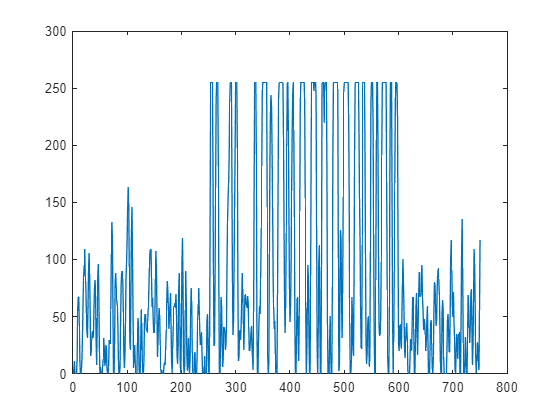

plot(ADCsignal2)

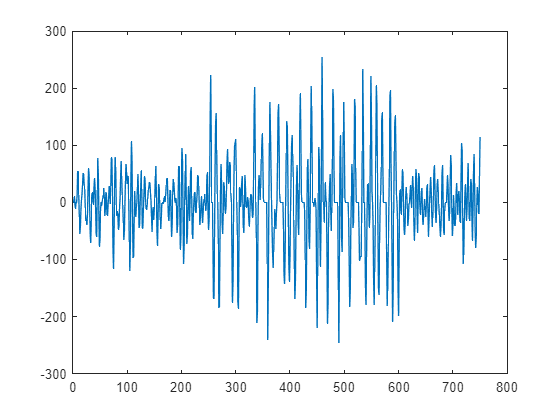

plot(diferencijuotasPilnas)

index_y

index_y = 313

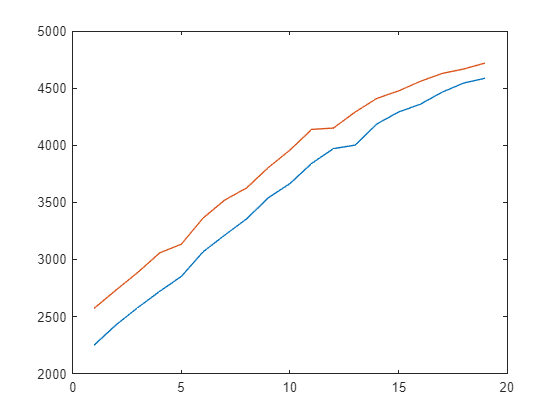

norm_preambules_max1_error_min = abs(viso_max_duom - preambules_max1_error_min);
norm_preambules_max1_error_max = abs(preambules_max1_error_max - viso_max_duom);
norm_preambules_max2_error_min = abs(viso_max_duom2 - preambules_max2_error_min);
norm_preambules_max2_error_max = abs(preambules_max2_error_max - viso_max_duom2);

viso_skirtumas = viso_max_duom - viso_max_duom2;

skirtumasLowHigh = (preambules_max1_error_min - preambules_max2_error_max) ./ viso_max_duom;

kiekvienas_skirtumas = kiekvienas_max - kiekvienas_max2;
kiekvienas_mean = mean(kiekvienas_skirtumas);
kiekvienas_mean_skirtumas = kiekvienas_skirtumas - kiekvienas_mean;

kiekvienas_max_deviacija = mean(kiekvienas_max) - kiekvienas_max;

minKvantiliai = [];
maxKvantiliai = [];
for i = 1:19
    minKvantiliai = [minKvantiliai, nonzeros(quantile(kiekvienas_max(i, :), 0.25))];
    maxKvantiliai = [maxKvantiliai, nonzeros(quantile(kiekvienas_max(i, :), 0.75))];
end

plot(minKvantiliai)
hold on
plot(maxKvantiliai)
hold off

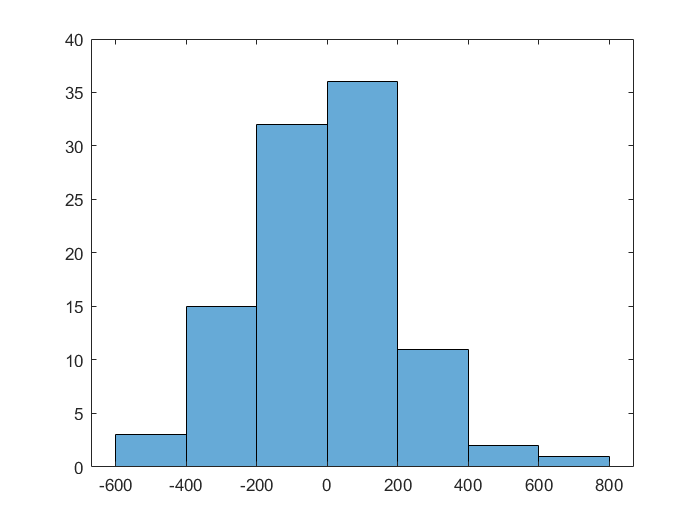

rodomasIndex = 5;

histogramai = nonzeros(kiekvienas_max(rodomasIndex, :));
histogramai = mean(histogramai) - histogramai;

histograma = histogram(histogramai);

Q = quantile(histogramai, 0.25)

Q = -142.3200

rodomasIndex = 1;
rangeas = 1:19;

%p = polyfit([0, viso_viso_eng(rodomasIndex, :)], [0, viso_max_duom(rodomasIndex, :)], 2);
%p = polyfit(viso_viso_eng(rodomasIndex, rangeas), viso_max_duom(rodomasIndex, rangeas)-norm_preambules_max1_error_min(rodomasIndex, rangeas), 2);
p = polyfit([0, viso_viso_eng(rodomasIndex, rangeas)], [1000, viso_max_duom(rodomasIndex, rangeas)], 2);
%p = polyfit([0, viso_viso_eng(rodomasIndex, rangeas)], [1000, maxKvantiliai(rodomasIndex, rangeas)], 2);
p

p =    -0.0000    0.2328  968.2859


p_fit_x = 0:1000:25000;
p_fit = polyval(p, p_fit_x);
p_fitt = 2000^2*p(1)+2000*p(2)+p(3)%-1285.4 + 3000*1.0267

p_fitt = 1.4244e+03

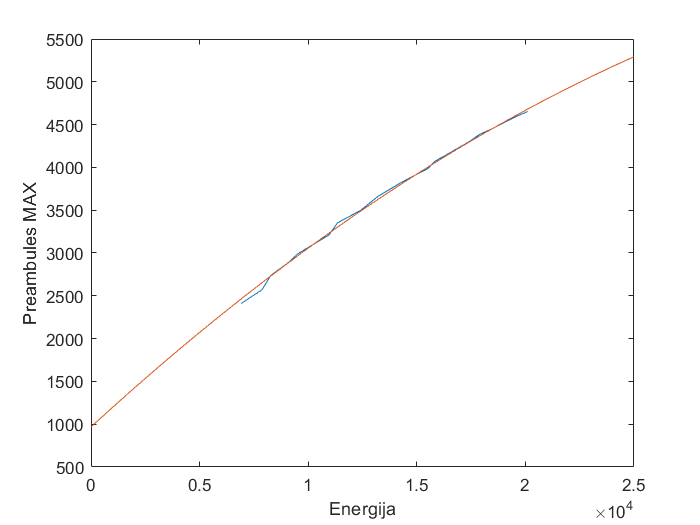

plot(viso_viso_eng(rodomasIndex, :), viso_max_duom(rodomasIndex, :))
xlabel("Energija")
ylabel("Preambules MAX")
hold on
plot(p_fit_x, p_fit)
hold off

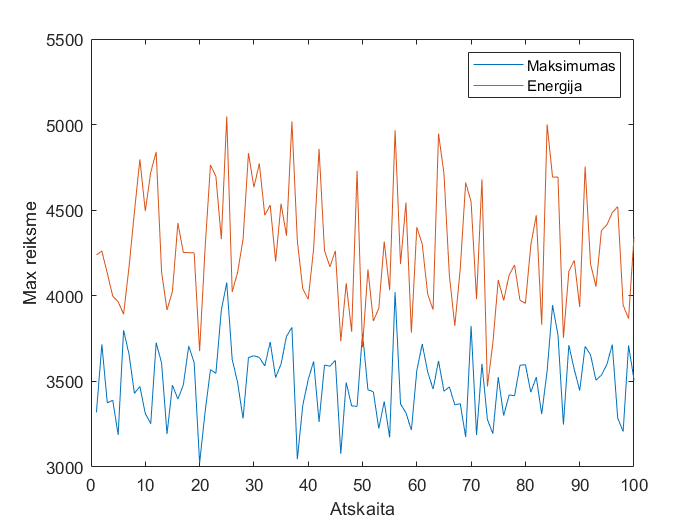


figure
plot(kiekvienas_max(8, :))
hold on
plot(kiekvienas_eng(8, :))
hold off
legend("Maksimumas", "Energija")
xlabel("Atskaita")
ylabel("Max reiksme")

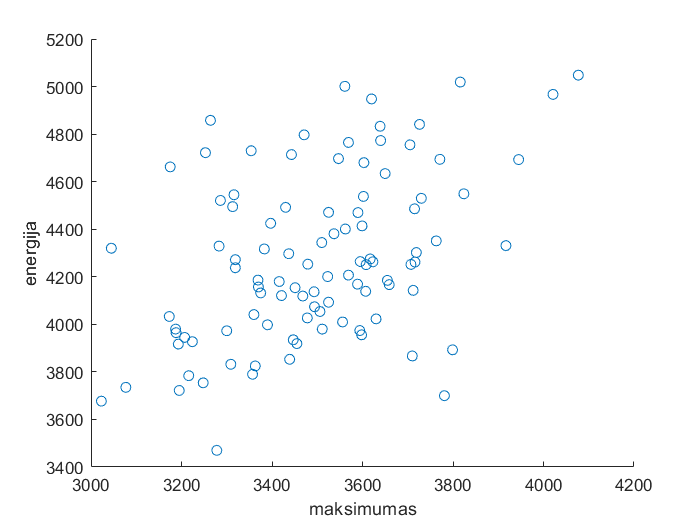


figure
scatter(kiekvienas_max(8, :), kiekvienas_eng(8, :))
xlabel("maksimumas")
ylabel("energija")

R = corr2(kiekvienas_max(8, :), kiekvienas_eng(8, :))

R = 0.4400

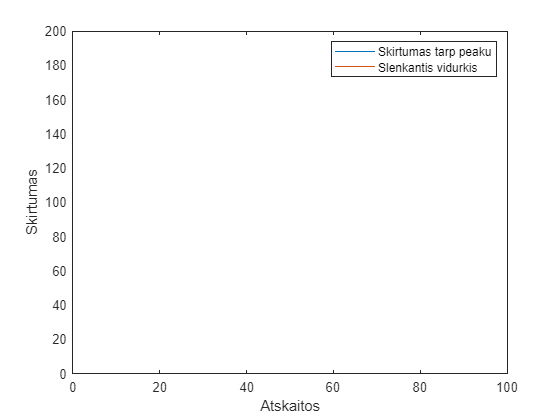


figure
plot(kiekvienas_skirtumas(rodomasIndex, :))
hold on
plot(movmean(kiekvienas_skirtumas(rodomasIndex, :), 50))
xlabel("Atskaitos")
ylabel("Skirtumas")
legend("Skirtumas tarp peaku", "Slenkantis vidurkis")
hold off

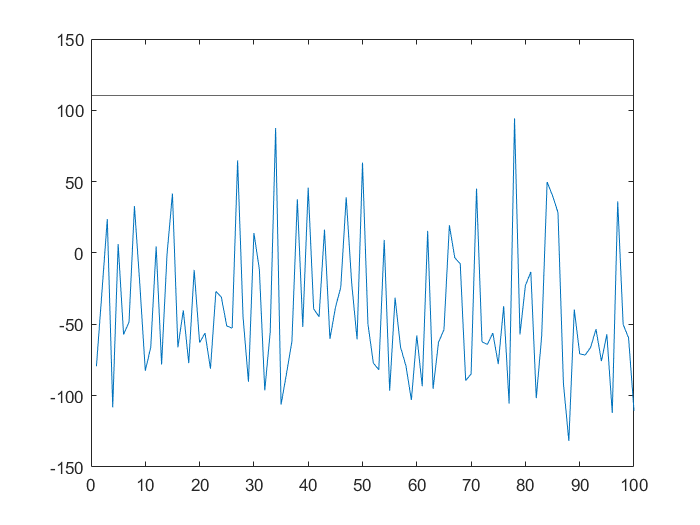

plot(kiekvienas_mean_skirtumas(rodomasIndex, :))
hold on
yline(kiekvienas_mean(rodomasIndex))
hold off

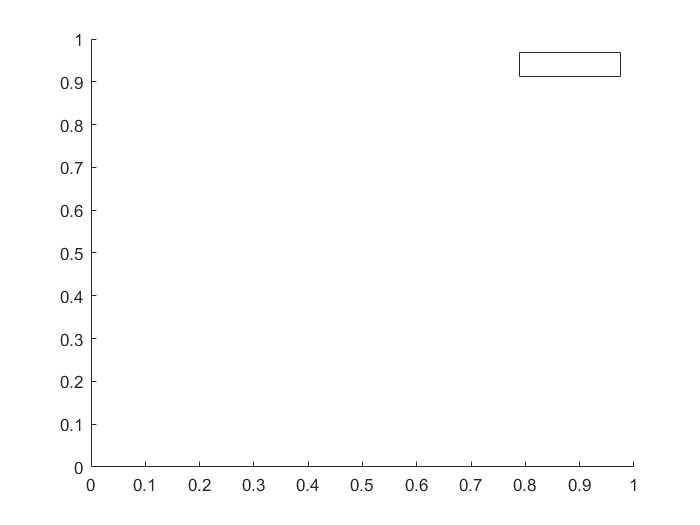


figure
%errorbar(amplitude_duom, preambules_max_duom, preambules_max1_error_min, preambules_max1_error_max)

%errorbar(amplitude_duom, preambules_max_duom2, preambules_max2_error_min, preambules_max2_error_max)
%legend(["Maksimumas 1", "Maksimumas 2"])
legend()
hold off

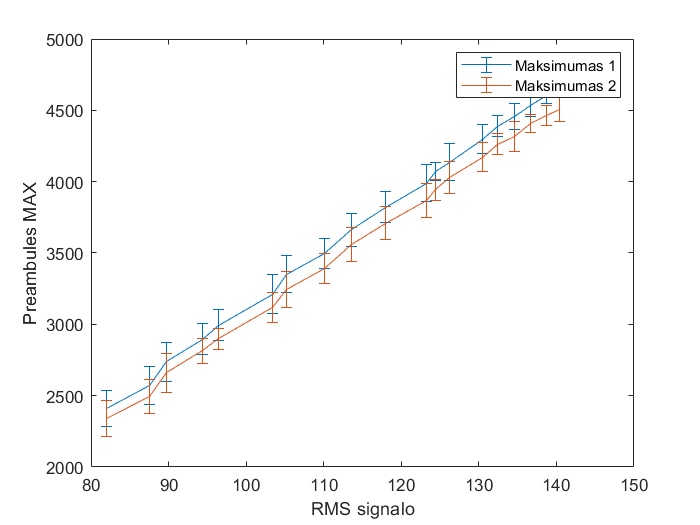


figure
%plot(rms_duom, viso_neteisingi(rodomasIndex, 2:length(viso_neteisingi)))
%plot(rms_duom, viso_neteisingi)
xlabel("RMS")
ylabel("Neteisingu peaku skaicius is 100")
errorbar(rms_duom, viso_max_duom(rodomasIndex, :), norm_preambules_max1_error_min(rodomasIndex, :), norm_preambules_max1_error_max(rodomasIndex, :))
xlabel("RMS signalo")
ylabel("Preambules MAX")
hold on
errorbar(rms_duom, viso_max_duom2(rodomasIndex, :), norm_preambules_max2_error_min(rodomasIndex, :), norm_preambules_max2_error_max(rodomasIndex, :))
legend(["Maksimumas 1", "Maksimumas 2"])
hold off

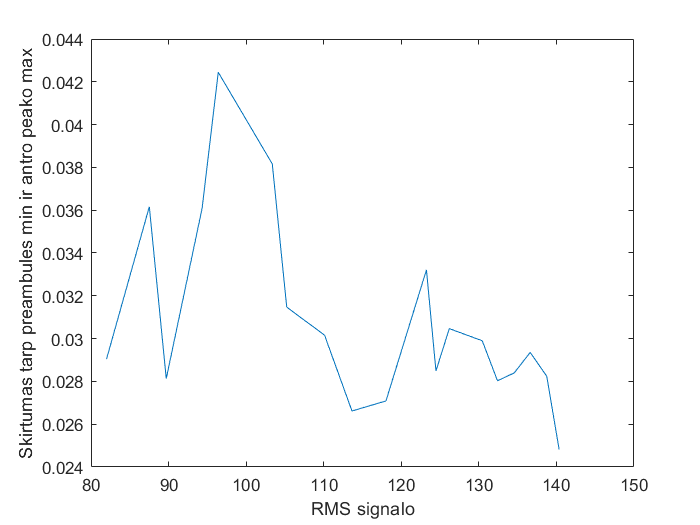

figure
plot(rms_duom, skirtumasLowHigh(rodomasIndex, :))
xlabel("RMS signalo")
ylabel("Skirtumas tarp preambules min ir antro peako max")

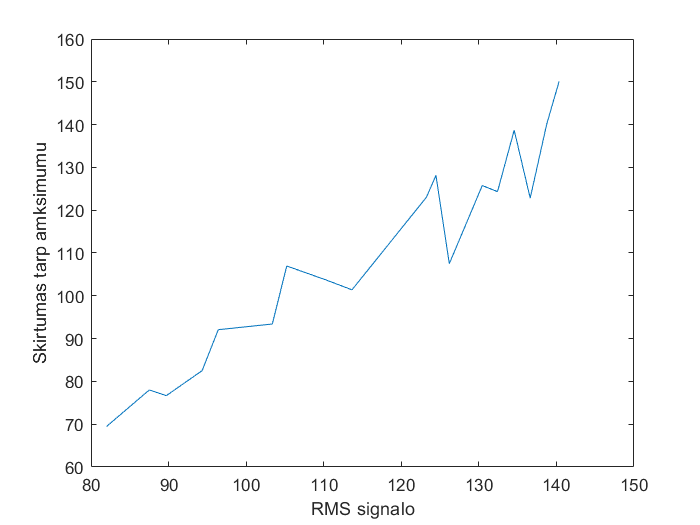


figure
plot(rms_duom, viso_skirtumas(rodomasIndex, :))
xlabel("RMS signalo")
ylabel("Skirtumas tarp amksimumu")

%Pavirsius nuo pastumimo, rms ir skirtumo tarp peaku, turi sugeneruoti
%pastumima visa
surf(rms_duom, viso_pastumimas, viso_skirtumas)

Error using surf (line 71)
Z must be a matrix, not a scalar or vector.

%surf(rms_duom, viso_langas , viso_skirtumas)
%surf(eng_duom, viso_langas , viso_skirtumas)
xlabel("RMS");
ylabel("Pastumimas");
zlabel("Skirtumas");
figure
%scatter3(viso_viso_rms(:), viso_viso_langas(:), viso_skirtumas(:), 10, viso_skirtumas(:))
%scatter3(viso_viso_eng(:), viso_viso_langas(:), viso_skirtumas(:), 10, viso_skirtumas(:))
scatter3(viso_viso_pastumimas(:), viso_viso_rms(:), viso_skirtumas(:), 10, viso_skirtumas(:))
xlabel("X RMS")
ylabel("Y Lango ilgis")
zlabel("Z Skirtumas")